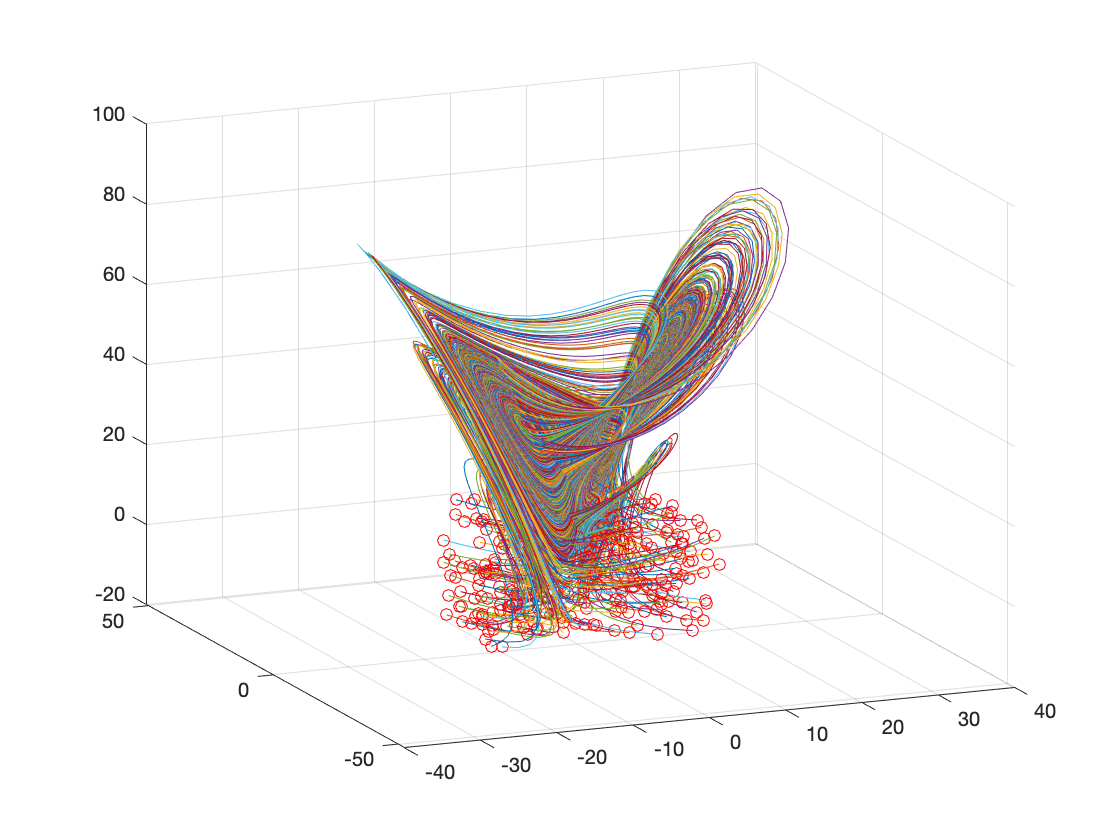

clear all, close all

% Simulate Lorenz system
dt=0.01; T=8; t=0:dt:T;
b=8/3; sig=10; r=[10 28 40];

Lorenz = @(t,x,r)([ sig * (x(2) - x(1))       ; ...
                  r * x(1)-x(1) * x(3) - x(2) ; ...
                  x(1) * x(2) - b*x(3)         ]);              
ode_options = odeset('RelTol',1e-10, 'AbsTol',1e-11);

input=[]; output=[];
for j=1:100  % training trajectories
    for i = 1:3
    x0=30*(rand(3,1)-0.5);
    [t,y] = ode45(@(t,x) Lorenz(t,x,r(i)),t,x0);
    n = length(t);
    input=[input; y(1:end-1,:) r(i)*ones(n-1,1)];
    output=[output; y(2:end,:) r(i)*ones(n-1,1)];
    plot3(y(:,1),y(:,2),y(:,3)), hold on
    plot3(x0(1),x0(2),x0(3),'ro')
    end
end
grid on, view(-23,18)

net = feedforwardnet([10 10 10]);
net.layers{1}.transferFcn = 'logsig';
net.layers{2}.transferFcn = 'radbas';
net.layers{3}.transferFcn = 'purelin';
net = train(net,input.',output.');

save('lorenz_net')

load('lorenz_net.mat')

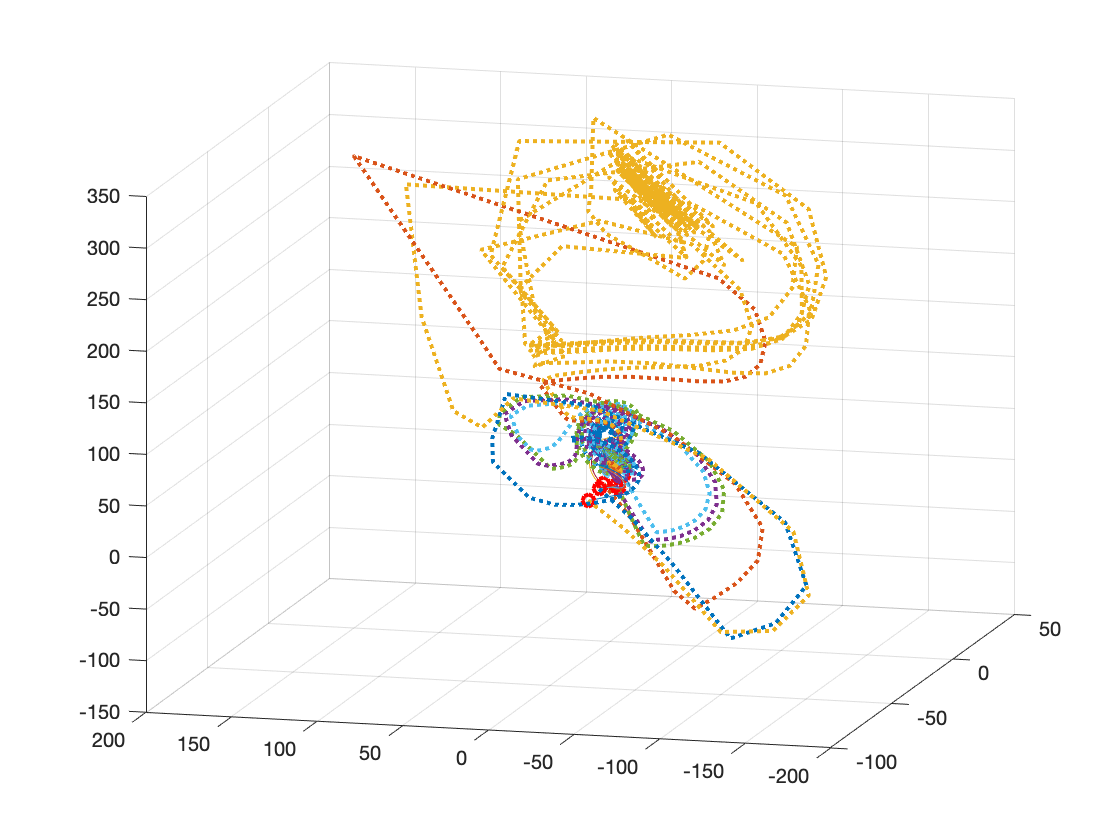

figure(2)
x0=20*(rand(3,1)-0.5);
[t,y] = ode45(@(t,x) Lorenz(t,x,17),t,x0);
plot3(y(:,1),y(:,2),y(:,3)), hold on
plot3(x0(1),x0(2),x0(3),'ro','Linewidth',[2])
grid on

x0 = [x0;17];
ynn(1,:)=x0;
for jj=2:length(t)
    y0=net(x0);
    ynn(jj,:)=y0.'; x0=y0;
end
plot3(ynn(:,1),ynn(:,2),ynn(:,3),':','Linewidth',[2])

figure(3)
subplot(3,2,1), plot(t,y(:,1),t,ynn(:,1),'Linewidth',[2])
title('NN on \rho = 17')
subplot(3,2,3), plot(t,y(:,2),t,ynn(:,2),'Linewidth',[2])
subplot(3,2,5), plot(t,y(:,3),t,ynn(:,3),'Linewidth',[2])


figure(2)
x0=20*(rand(3,1)-0.5);
[t,y] = ode45(@(t,x) Lorenz(t,x,17),t,x0);
plot3(y(:,1),y(:,2),y(:,3)), hold on
plot3(x0(1),x0(2),x0(3),'ro','Linewidth',[2])
grid on

x0 = [x0;35];
ynn(1,:)=x0;
for jj=2:length(t)
    y0=net(x0);
    ynn(jj,:)=y0.'; x0=y0;
end
plot3(ynn(:,1),ynn(:,2),ynn(:,3),':','Linewidth',[2])

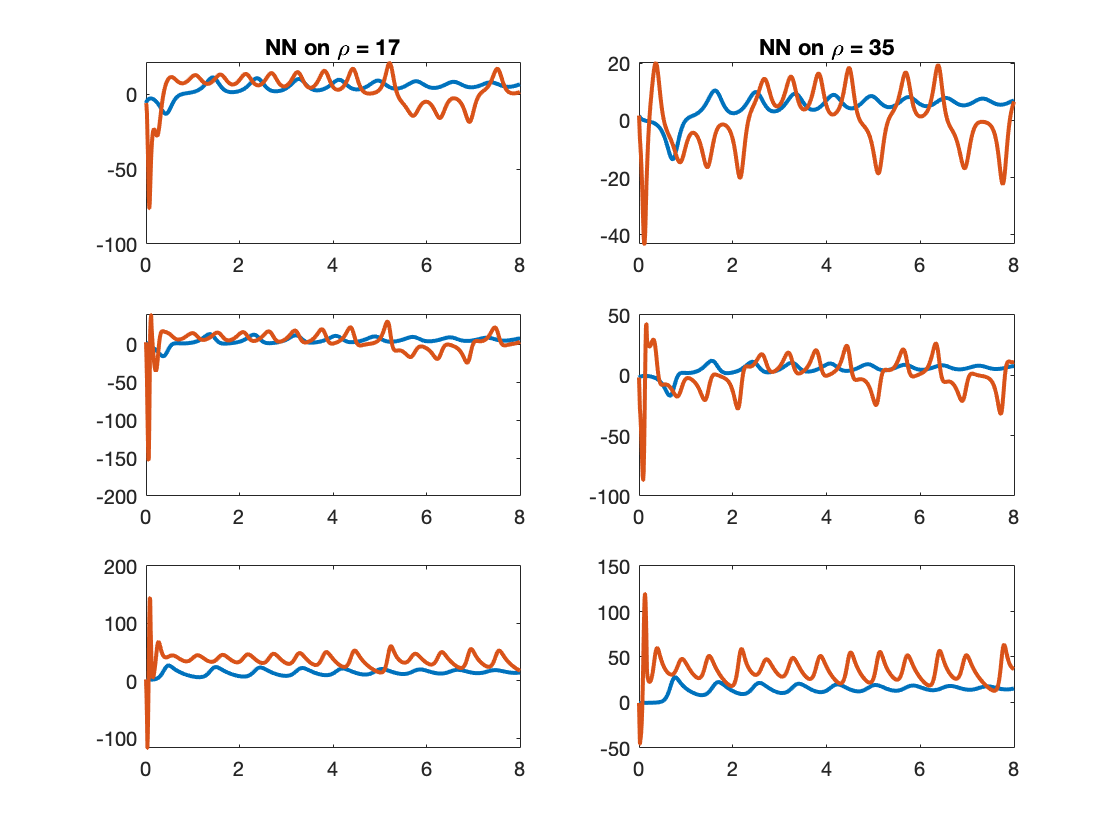


figure(3)
subplot(3,2,2), plot(t,y(:,1),t,ynn(:,1),'Linewidth',[2])
title('NN on \rho = 35')
subplot(3,2,4), plot(t,y(:,2),t,ynn(:,2),'Linewidth',[2])
subplot(3,2,6), plot(t,y(:,3),t,ynn(:,3),'Linewidth',[2])

figure(2), view(-75,15)

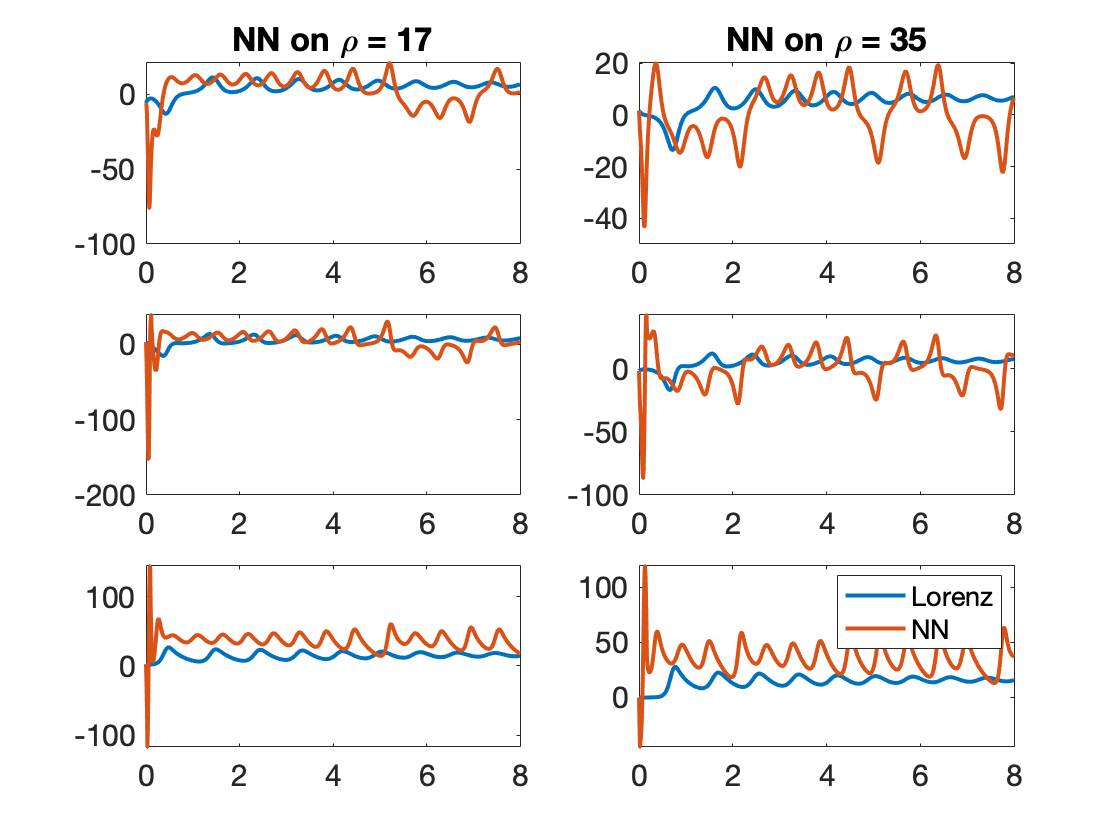

figure(3)
subplot(3,2,1), set(gca,'Fontsize',[15],'Xlim',[0 8])
subplot(3,2,2), set(gca,'Fontsize',[15],'Xlim',[0 8])
subplot(3,2,3), set(gca,'Fontsize',[15],'Xlim',[0 8])
subplot(3,2,4), set(gca,'Fontsize',[15],'Xlim',[0 8])
subplot(3,2,5), set(gca,'Fontsize',[15],'Xlim',[0 8])
subplot(3,2,6), set(gca,'Fontsize',[15],'Xlim',[0 8])
legend('Lorenz','NN')

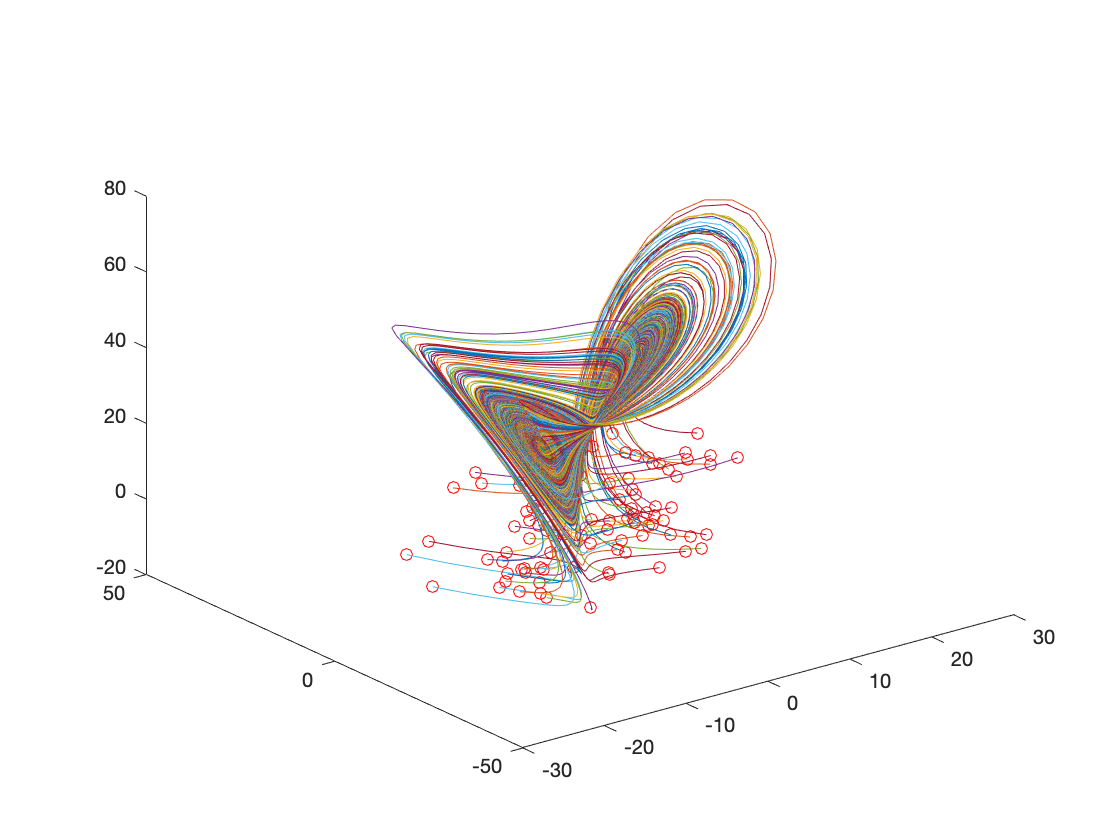

%lobe identification
clear all, close all
% Simulate Lorenz system
dt=0.01; T=8; t=0:dt:T;
b=8/3; sig=10; r=28 ;

Lorenz = @(t,x)([ sig * (x(2) - x(1))       ; ...
                  r * x(1)-x(1) * x(3) - x(2) ; ...
                  x(1) * x(2) - b*x(3)         ]);              
ode_options = odeset('RelTol',1e-10, 'AbsTol',1e-11);

input=[]; output=[]; lobeTransition = [0];
for j=1:100  % training trajectories
    
    x0=30*(rand(3,1)-0.5);
    [t,y] = ode45(Lorenz,t,x0);
    input=[input; y(1:end-1,:)];
    output=[output; y(2:end,:)];
    for i = 1:length(t)-1
        if sign(y(i,1))~=sign(y(i+1,1)) 
            lobeTransition= [lobeTransition;1];
        else
            lobeTransition = [lobeTransition;0];
        end      
        
    end
    figure(4)
    %subplot(2,1,1)
    plot3(y(:,1),y(:,2),y(:,3)), hold on
    plot3(x0(1),x0(2),x0(3),'ro')
    figure(5)
    plot(y(:,1),y(:,2)), hold on
    xlabel('x')
    ylabel('y')
    
end

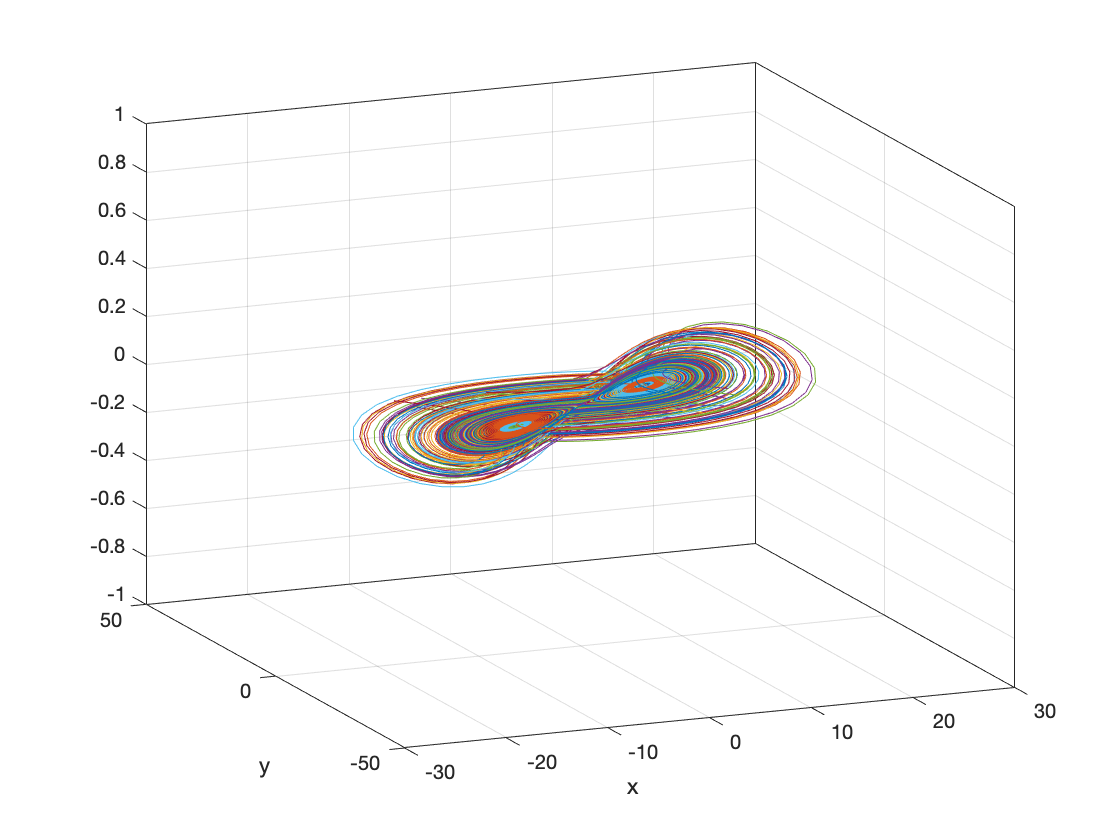

grid on, view(-23,18)

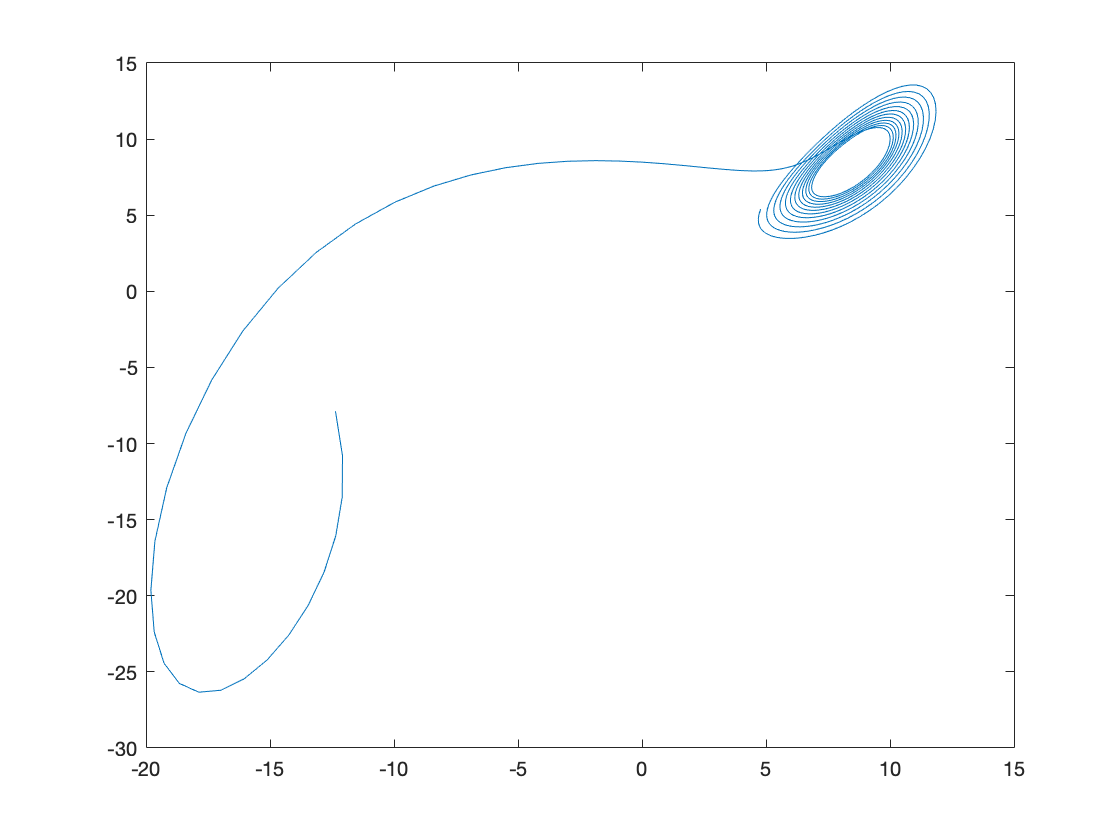

input = [input lobeTransition(1:end-1)];

output = [output lobeTransition(2:end)];

net2 = feedforwardnet([10 10 10]);
net2.layers{1}.transferFcn = 'logsig';
net2.layers{2}.transferFcn = 'radbas';
net2.layers{3}.transferFcn = 'purelin';
net2 = train(net2,input.',output.');

save('lobe_net','input','output','net2','t','y')

load('lobe_net.mat')
lobe_ac1 =[]
for i = 1:10
x0=20*(rand(3,1)-0.5);
[t,y] = ode45(@(t,x) Lorenz(t,x),t,x0);
figure (6)


lobe_ac1 =

     []



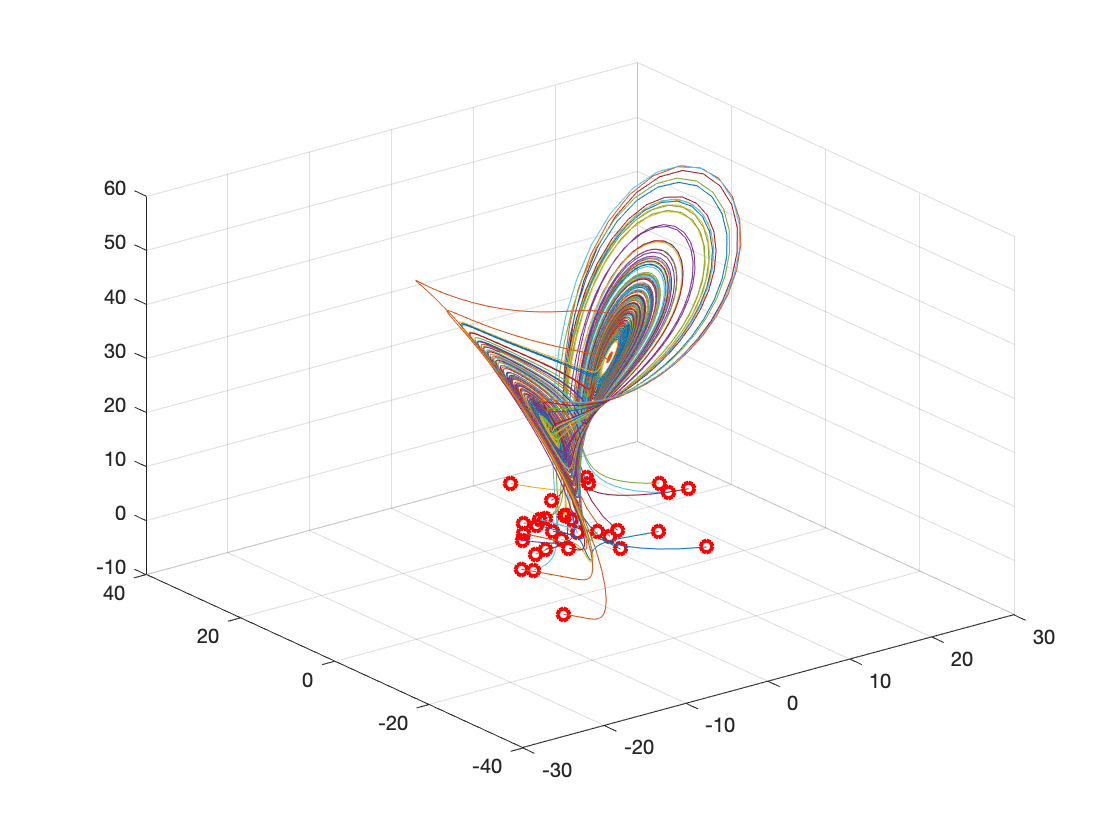

plot3(y(:,1),y(:,2),y(:,3)), hold on
plot3(x0(1),x0(2),x0(3),'ro','Linewidth',[2])
grid on

x0 = [x0;0];
ynn(1,:)=x0;
for jj=2:length(t)
    y0=net2(x0);
    ynn(jj,:)=y0.'; x0=y0;
end
%find true lobe transitions
test_lobe = [0];
for i = 1:length(t)-1
        if sign(y(i,1))~=sign(y(i+1,1)) 
            test_lobe= [test_lobe;1];
        else
            test_lobe = [test_lobe;0];
        end      
        
end
numTrans = length(find(test_lobe == 1));
%threshold 
nn_lobe = [];
for j = 1:length(t)
    if ynn(i,4) >= .5
        nn_lobe(i) = 1;
    else nn_lobe(i) = 0;
    end
end
%calculate accuracy
m = test_lobe(2:end)' + nn_lobe;
mm = find(m == 2);
lobe_ac1 = [lobe_ac1;size(mm,2)/800];
end
